# Primer ejemplo del semestre

## Modelado de un saltador de un bungee

#### Solución analítica


$$\vec{F} = mg - c_d v^2 = m \vec{a}$$



$$a = g - \frac{cd}{m} v^2$$



$$\frac{dv}{dt} = \frac{cd}{m} v^2$$


syms v(t) g cd m
eqn = diff(v, t) == g - (cd/m)*v^2;
cnd = v(0) == 0;
vSym = dsolve(eqn, cnd) % Solves differential equation

$$vSym = \frac{\sqrt{g}\,\sqrt{m}\,\tanh\left(\frac{\sqrt{\mathrm{cd}}\,\sqrt{g}\,t}{\sqrt{m}}\right)}{\sqrt{\mathrm{cd}}}$$

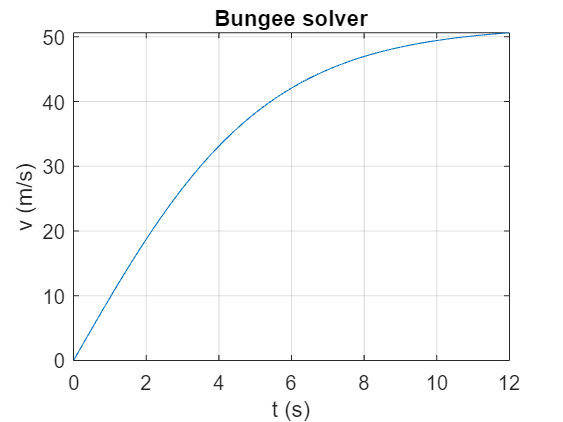


g = 9.81;
m = 68.1;
cd = 0.25;

vel = subs(vSym); % Substitutes values into sym equation
t = [0 12];

fplot(vel, t)
hold on
grid on
ylabel('v (m/s)')
xlabel('t (s)')
title('Bungee solver')

#### Solución numérica

Utilizando la serie de Taylor podemos hacer constantes aproximaciones, ya que conocemos el valor inicial del problema.


$$\frac{dv}{dt} = \frac{v_{i+1} - v_i}{t_{i+1} - t_i} = \frac{v_{i+1} - v_i}{h}$$



$$v_{i+1} = v_i + \frac{dv}{dt} h$$



$$v_{i+1} = v_i + (g - \frac{cd}{m} v_i^2)h$$


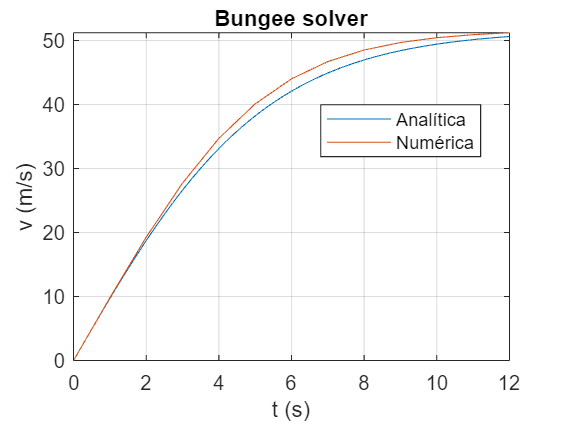

h = 1;
t = 0:h:12;
n = length(t);
v = zeros(size(t));

for i = 1:n-1
    v(i+1) = v(i) + (g - (cd/m) * v(i)^2)*h;
end

plot(t, v)
legend('Analítica', 'Numérica', 'Location','best')
hold off